# Robot Detector

Copyright 2018-2019 The MathWorks, Inc.

## Overview

The Robot Detector allows you to simulate vision-based multi-robot detectors for visualization and algorithm prototyping. It includes a MATLAB and Simulink interface.

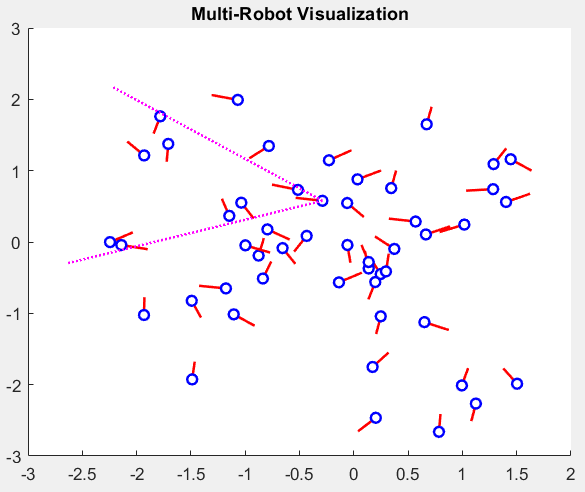

**Properties:**

- **Map: **A [`robotics.OccupancyGrid`](matlab: doc robotics.OccupancyGrid) or [`robotics.BinaryOccupancyGrid`](matlab: doc robotics.BinaryOccupancyGrid)

- **Robot detector offset:** A 2-by-1 array of $[x; y]$ offset from the vehicle

- **Robot detector angle:** Sensor orientation, in radians, relative to the vehicle $x$-axis 

- **Sensor field of view:** Sensor angular range, in radians, symmetric about the sensor $x$-axis

- **Maximum range:** The sensor maximum range, in meters.

- **Maximum number of detections:** The maximum robot detections returned. Detections are sorted from nearest to farthest.

- **Sample time: **Sensor sample time (Simulink only)

**Inputs:**

- None

**Outputs:**

- **Detections: **A variable-sized array up to size `maxDetections`-by-3. Each row corresponds to `[range,angle,idx]` of an object detection. Range is in meters, and angle is in radians. The third column is the index of the robot, ranging from 1 to the maximum number of robots in the environment.

## MATLAB Usage

Create a `MultiRobotEnv` with a certain number of robots. Then, attach a `RobotDetector` object to a specific robot.

numRobots = 10;
env = MultiRobotEnv(numRobots);

robotIdx = 5;
detector = RobotDetector(env,robotIdx)

detector =   RobotDetector with properties:

         robotIdx: 5
     sensorOffset: [0 0]
      sensorAngle: 0
      fieldOfView: 1.0472
         maxRange: 5
    maxDetections: 3
       sampleTime: 0.1000


Configure the sensor properties.

load exampleMap
detector.sensorOffset = [0.2 0];
detector.sensorAngle = 0;
detector.fieldOfView = pi/2;
detector.maxRange = 4;
detector.maxDetections = 5

detector =   RobotDetector with properties:

         robotIdx: 5
     sensorOffset: [0.2000 0]
      sensorAngle: 0
      fieldOfView: 1.5708
         maxRange: 4
    maxDetections: 5
       sampleTime: 0.1000


Simulate and display the object detections the map and vehicle pose.

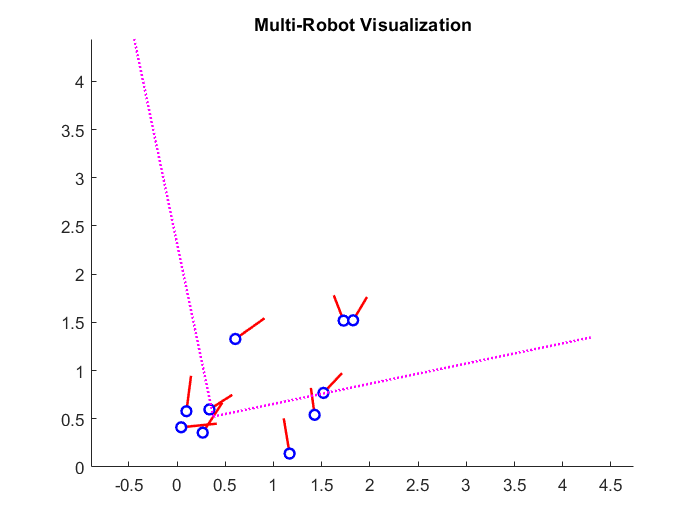

rng(21)
robotPoses = 2*rand(3,numRobots);
env(1:numRobots,robotPoses);

detections = step(detector)

detections =     0.8360    0.3019    3.0000
    1.1686   -0.7808    7.0000
    1.6778   -0.3576    6.0000
    1.7605   -0.3892    9.0000


**Examples**

- [Multi-robot swarm behavior](matlab:edit mrsSwarmTeams)

## Simulink Usage

Use the **Robot Detector** block from the **Environments** section of the [block library](matlab:mobileRoboticsLib). 

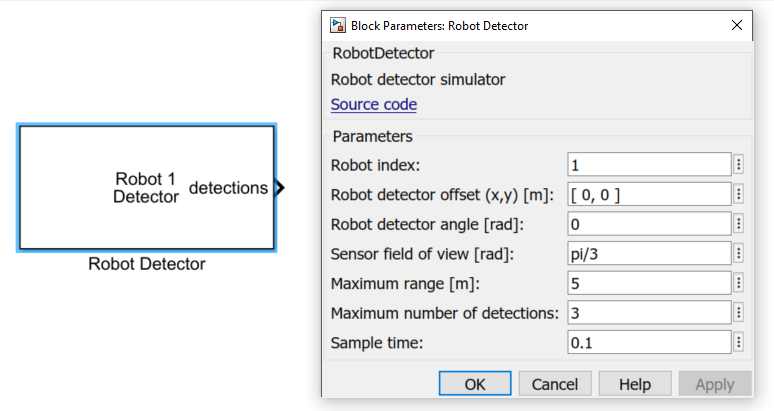

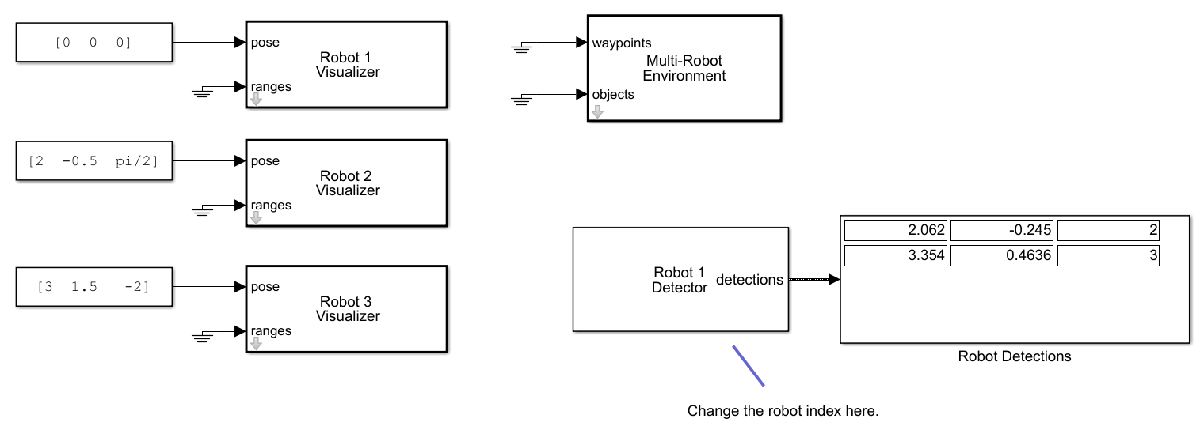

**Examples**

- [Robot detector example](matlab:mrsRobotDetectorModel)

- [Obstacle avoidance example](matlab:mrsMultiRobotAvoidance)